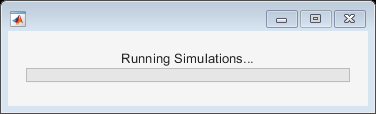

% Set simulation parameters
numberOfSimulations = 100;
numberOfIterations = 200000;

T_a = Token("TokenA", true, false, 1);
T_b = Token("TokenB", false, true, 0);
initialT_bPrice = 78.32;
totalT_a = 1.2*10^8;
totalT_b = 1.0*10^6;
freeT_a = totalT_a*0.7;
freeT_b = totalT_b*0.7;

walletExpRate = 0.000008;
poolFee = 0.003;

sigma = 0.00000001:0.00000001:0.002;

poolRecoveryPeriod = 36;
baseVirtualPool = 6.7215e7;
virtualLiquidityPool = ImprovedVirtualLiquidityPool(T_a, T_b, ...
    initialT_bPrice, baseVirtualPool, poolRecoveryPeriod);

totalReserves = 0.1 * totalT_a;

% Initialize arrays to store results
results = cell(numberOfSimulations, 1);

% Create a waitbar
h = waitbar(0, 'Running Simulations...');




% Run simulations
for i = 1:numberOfSimulations
    fprintf('Running Simulation %d\n', i);

    % Create a new instance of the simulation
    simulation = AlgorithmicStablecoinSimulation(T_a, T_b, initialT_bPrice, ...
        totalT_a, totalT_b, freeT_a, freeT_b, virtualLiquidityPool, numberOfIterations, ...
        walletExpRate, poolFee, sigma(i), totalReserves);

    simulation.setVolatilityArray(sigma);

    % Run the simulation
    [T_aPrices, T_bPrices, probA, probB, delta, ...
        totalT_aSupply, totalT_bSupply, freeT_a_results, freeT_b_results] = ...
        simulation.runSimulation();

    % Store results in a struct
    resultData = struct(...
        'T_aPrices', T_aPrices, ...
        'T_bPrices', T_bPrices, ...
        'probA', probA, ...
        'probB', probB, ...
        'delta', delta, ...
        'totalT_aSupply', totalT_aSupply, ...
        'totalT_bSupply', totalT_bSupply, ...
        'freeT_a', freeT_a, ...
        'freeT_b', freeT_b ...
        );

    % Store struct in results cell array
    results{i} = resultData;

    % Update waitbar
    waitbar(i / numberOfSimulations, h, sprintf('Running Simulations... %d%%', round((i / numberOfSimulations) * 100)));
end

Running Simulation 1




% Close the waitbar
close(h);

% Save results to a file
save('simulation_results_increasingVolatility_improvedVLPAndReserves.mat', 'results');
fprintf(['Simulations completed and results saved to' ...
    ' simulation_results_increasingVolatility_improvedVLPAndReserves.mat\n']);
